# 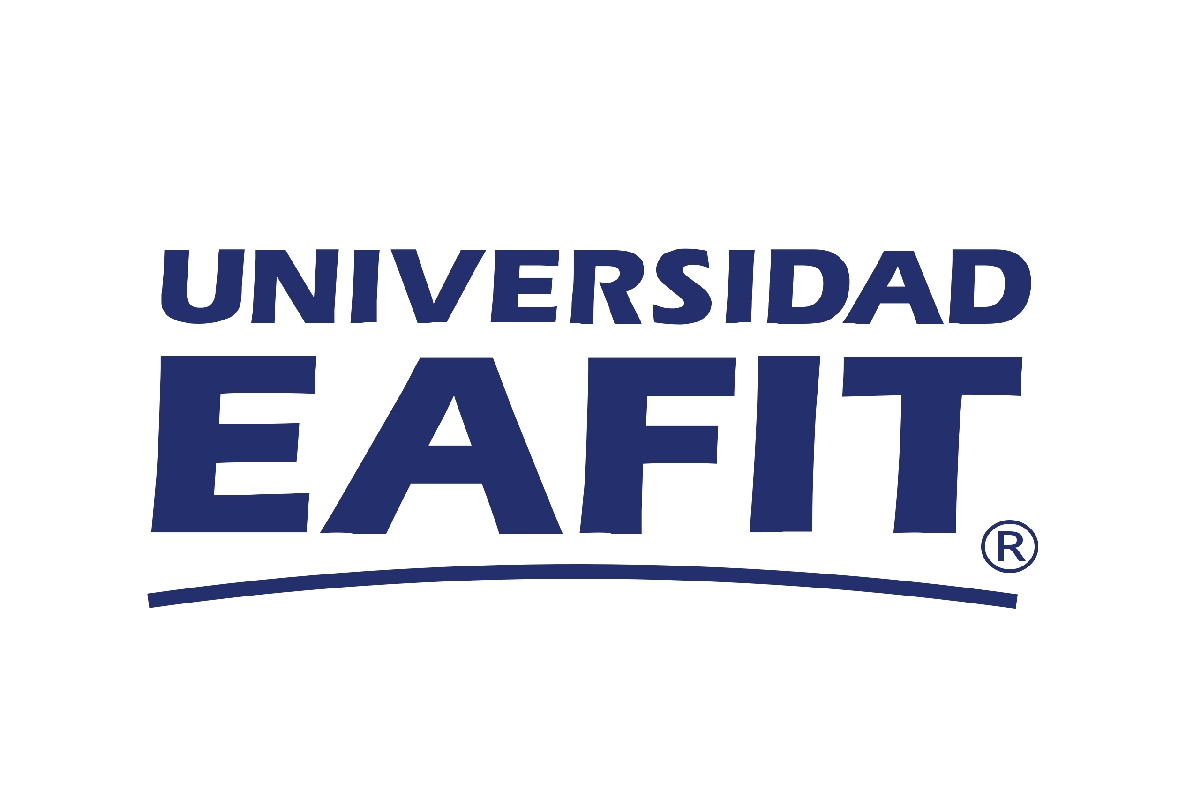                            Modelo del crecimiento de un tumor

Por Miguel Chacón y Felipe Henao, Universidad EAFIT.

## 1. Introducción 

En el desarrollo de este proyecto nos basamos en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$. El modelo de este trabajo representa el crecimiento de un tumor y como es su respuesta a un tratamiento, hay diversos factores que intervienen en este proceso, principalmente la severidad de la enfermedad, la aplicación del tratamiento y la fuerza del sistema inmune del paciente.

En el modelo se incluyen células inmunitarias cuyo crecimiento puede verse afectado por la presencia del tumor, las células inmunitarias pueden destruir células tumorales por medio de un proceso cinético. También se incluyen unos términos de competencia, es decir, las células normales y las tumorales compiten por los recursos disponibles, mientras que las células inmunitarias y las tumorales compiten en una relación depredador-presa. En el modelo $ I(t)$ denota el número de células inmunitarias en el tiempo $t$, $T(t)$ el número de células tumorales o tumorales en el tiempo $t$, $N(t)$ el número de células normales, o huésped, en el tiempo t.

Se considera que la fuente de las células inmunitarias está fuera del sistema, por lo que es razonable suponer una tasa de afluencia constante s. Además, en ausencia de cualquier tumor, las células morirán a una tasa per cápita d1, lo que resulta en un tamaño de población a largo plazo de s/$d_1
$ células.

La presencia de células tumorales estimula la respuesta inmunitaria, representada por el término de crecimiento no lineal positivo de las células inmunitarias


$$\frac{\rho I(t)T(t)}{\alpha + T(t)}$$


$\rho$ y $\alpha$ son constantes positivas.

La reacción de las células inmunes y tumorales puede resultar en la muerte de las células tumorales o en la inactivación de las células inmunes, representadas por los dos términos de competición

$\frac{dI}{dt} = -c_1I(t)T(t) $ y $\frac{dT}{dt} = -c_2I(t)T(t)$

Tanto las células tumorales como las normales se modelan mediante una ley de crecimiento logística, con los parámetros $r_i$ y $b_i$ que representan las tasas de crecimiento $\textit{per cápita}$ y las capacidades de carga recíprocas de los dos tipos de células: $i = 1$ identifica los parámetros asociados al tumor, e $i = 2$ los asociados al tejido normal. Además, hay dos términos que representan la competencia entre las células tumorales y las del huésped. 

Al juntar todos los términos mencionados anteriormente se obtiene el siguiente sistema de ecuaciones diferenciales ordinarias.


$$\dot{N} = r_2 N(1-b_2N)-c_4TN$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I$$


Se añade el efecto de la droga a este sistema. Se denota por $u(t)$ la cantidad de fármaco en la zona del tumor en el momento $t
$. Además, se supone que el fármaco mata todos los tipos de células, pero que la tasa de destrucción diferente para cada tipo de célula, con una curva de respuesta en todos los casos dada por una exponencial


$$F(u) = a(1-e^{-ku})$$


$F(u)$ es la muerte celular fraccionada para una cantidad dada de fármaco $U$, en el lugar del tumor. Dado que se desconocen los detalles de la farmacocinética, se establece $ k = 1$ como en estudios preliminares. Denotamos por $a_1$, $a_2$ y $a_3$ los tres coeficientes de respuesta diferentes. Se añaden estos términos al sistema de ecuaciones diferenciales anterior, así como una ecuación para $u(t)$, la cantidad de fármaco en el lugar del tumor. Ésta viene determinada por la dosis dada $v(t)$, y una tasa de decaimiento $\textit{per cápita}$ del fármaco una vez inyectado. Esta tasa de decaimiento incorpora todas las vías de eliminación del fármaco.

El sistema con interacción de fármacos viene dado por:


$$\dot{N} = r_2 N(1-b_2N)-c_4TN - a_3(1-e^{-u})N$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN - a_2(1-e^{-u})T$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I- a_1(1-e^{-u})I$$


### 
$$\dot{u}=v(t)-d_2u$$


### 1.1. Resumen del significado de términos

- $N(t)$: El número de células normales, o huésped, en el tiempo $t$. Se usa $N(0) = 1$

- $T(t)$: El número de células tumorales o tumorales en el tiempo $t$. Se usa $T(0) = 0.25$

- $I(t)$: Denota el número de células inmunitarias en el tiempo $t
$. Se usa $I(0) = 0.15$ y $I(0) = 0.10$

- $a_i$ : Fraccion de muerte celular, $a_3 \leq a_1 \leq a_2$.  Se usa $a_1 = 0.2$, $a_2 = 0.3 $, y $a_3 = 0.1 $

- $b_1,b_2$: capacidades de barrido, $b_1^{-1}\leq b_2^{-1} = 1$. Se usa $b_1 = b_2 = 1.0$

- $c_1,c_2,c_3,c_4$ : Terminos de competicion. Se usa $c_1 = 1.0$, $c_2 = 0.5 $, $c_3 = 1.0 $ y $c_4 = 1.0 $

- $d_1,d_2$ : tasas de muerte, $d_1$ es la tasa de muerte $\textit{per capita}$ de celulas inmunes, y $d_2$ es la tasa de muerte $\textit{per capita}$ de la droga. Se usa $d_1 = 0.2$ y $d_2 = 1.0 $

- $r_1,r_2$ : tasa por unidad de crecimiento. En el trabajo asumimos que la poblacion de celular tumorales crece mas rápido que la población de celulas normales, es decir, $r_1>r_2$. Se usa $r_1 = 1.5$ y $r_2 = 1.0$

- $s$ : Tasa de fuente inmunitaria. $0<s\leq0.5$. Se usa $s = 0.33$

- $\alpha$ : Tasa de umbral inmune. Se usa $\alpha = 0.3$

- $\rho
$ : Tasa de respuesta inmune. Se usa $\rho=0.01$, para simular un paciente con un sistema inmunologico comprometido

% Parametros
clear; clc; clf

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
a1=0.2; a2=0.3; a3=0.1;
b1=1.0; b2=1.0;
c1=1.0; c2=0.5; c3=1.0; c4=1.0;
d1=0.2; d2=1.0;
r1=1.5; r2=1;
s=0.33;
alpha=0.3;
rho=0.01;

### **1.2. Figura del diagrama de bloques y máscaras**

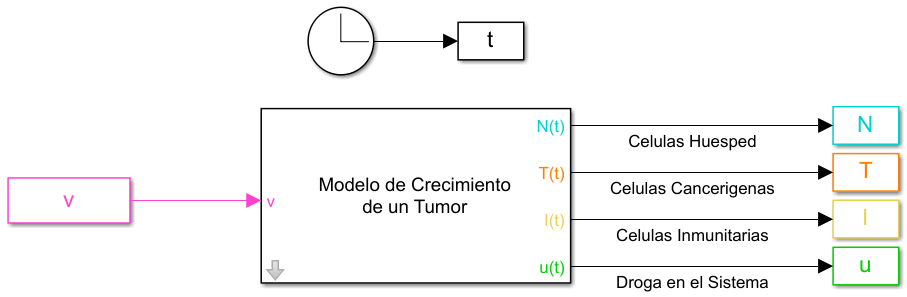

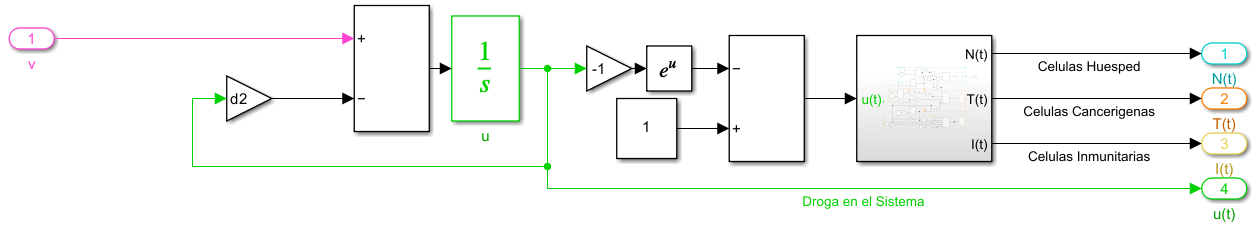

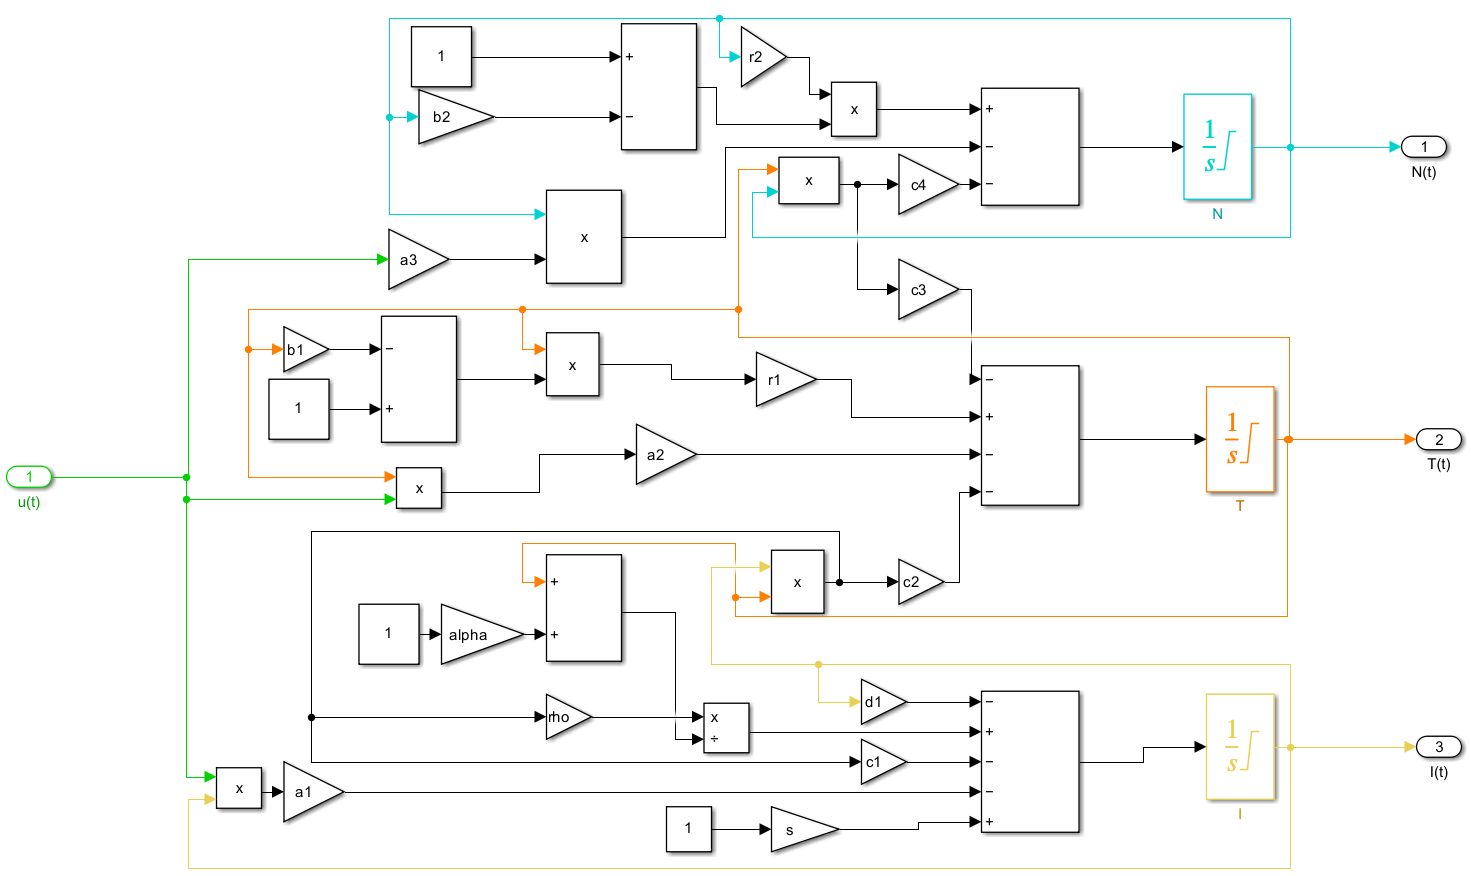

### 1.3. Hipótesis

## 2. Métodos

- Con base en el modelo de bloques y mascaras hecho en Simulink anteriormente y el modelo lineal hecho en la práctica anterior, se realizar un controlador lineal K con una referencia de cero, esto es, el controlador mueve los polos del sistema a valores escogidos y mantiene el sistema en el punto de operación, esto se hará tanto en tiempo continuo como en tiempo discreto.

- Para desarrollar el control lineal continuo, primero se linealizará el modelo alrededor de un punto, luego se evaluará la controlabilidad del modelo, para esto se va a calcular la matriz de controlabilidad del modelo y se evaluará su rango, la cual debe ser de ranco completo, y el número de condición, que nos puede decir que tan controlable es el modelo y si el control que se va a hacer es bueno o no.

- Después, usando la función *acker* de MATLAB, se encontrará el control lineal correspondiente a la ubicación donde se quiere poner los polos del sistema, este método sirve para sistemas SIMO, que es exactamente el tipo del sistema trabajado en la práctica, y se desarrollará el modelo de Simulink con el control lineal para el control no lineal. Para evaluar si el control lineal está bien, se correrá el modelo desarrollado moviendo las condiciones iniciales cerca del punto de operación y este debe regresar a dicho punto.

- Luego, se simulará el sistema en lazo cerrado con dicho controlador agregando distintas perturbaciones en la entrada en forma de un tren de pulsos de distintos anchos y altos, con alturas que incluso saquen el sistema del rango de linealidad. Esto lo haremos con el fin de evaluar la reacción del control con las perturbaciones.

- Este proceso anterior se hará también usando un control discreto. Para esto se discretizará el modelo lineal usando el mismo tiempo de muestreo obtenido anteriormente, y usando la función *acker* de MATLAB, se encontrará el control lineal discreto. Para escoger los polos del sistema discreto, se considera la relación entre $z
$ y $s$, la cual es $z=e^{sT_s}$, y se usará esta relación para hallar dichos polos usando los polos escogidos para el continuo. Luego se repite el mismo proceso hecho para el continuo, pero ahora con el discreto y la única diferencia es que se agrega un retenedor de orden cero para el modelo en lazo cerrado discreto, debido a que el controlador es discreto.

- Adicionalmente, se hará un análisis de sensibilidad e incertidumbre usando la herramienta GSUA disponible en Mathworks. Para el caso del análisis de incertidumbre se evaluará hasta que porcentaje de incertidumbre en los parámetros tiene sentido el diseño del controlador. Para el caso de la sensibilidad, se clasificará que parámetros del modelo son los más sensibles, con una incertidumbre del 20% en todos los parámetros, y se correrá usando los métodos OAT y Saltelli para evaluar si hay relaciones entre los parámetros.

## 3. Resultados

### 3.1. Control lineal

Primero, obtendremos nuevamente las matrices A, B, C y D correspondientes al modelo lineal, linealizando alrededor del mismo punto de equilibrio usado en la práctica 2, el cual también será nuestro punto de operación en esta práctica. Para el modelo lineal discreto, se usará el mismo tiempo de muestreo hallado en la práctica 2, que corresponde a 9.

t=0:0.1:150; 
v=[t' zeros(size(t,2),1)];
peq=[0.4934 0.4970 0.4649 0.10]';
veq=0.1;
Ts=9;
[A,B,C,D]=linmod('ModeloPractica',peq,veq);
sys=ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3        x4
   x1   -0.4933   -0.4934         0  -0.04464
   x2    -0.497   -0.7454   -0.2485   -0.1349
   x3         0   -0.4627   -0.7098  -0.08413
   x4         0         0         0        -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


Ahora discreizamos el sistema lineal continuo para un tiempo de muestreo de 9, como fue mencionado anteriormente

sysDisc=c2d(sys,Ts)

sysDisc =
 
  A = 
              x1         x2         x3         x4
   x1     0.3479    -0.3183     0.1167    0.01825
   x2    -0.3206     0.2947    -0.1091   -0.01693
   x3     0.2189    -0.2032    0.07695    0.01153
   x4          0          0          0  0.0001234
 
  B = 
            u1
   x1   0.1172
   x2  -0.2446
   x3  0.02473
   x4   0.9999
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 9 seconds
Discrete-time state-space model.


#### 3.1.1 Matriz de controlabilidad

Ahora, encontraremos la matriz de controlabilidad del sistema lineal para evaluar que tan controlable es el sistema, viendo s rango y su numero de condición.

Mc=[B A*B A^2*B A^3*B];
r=rank(Mc);
nc=cond(Mc);
tab=array2table([r,nc],'VariableNames',{'Rango','Número de Condición'});
disp(tab)

    Rango    Número de Condición
    _____    ___________________

      4            2429.2       



#### 3.1.2 Control lineal continuo

Ahora, usando el metodo de acker encontraremos los valores para el control lineal K para ubicar los polos en...

P=0.6*[-1,-1,-1,-1];
K=acker(A,B,P);

El control lineal obtenido es el siguiente

disp(K)

    1.8271   -3.7259    0.3277   -0.5485



Ahora corremos el modelo usando el control lineal usando condiciones iniciales cerca del punto de equilibrio

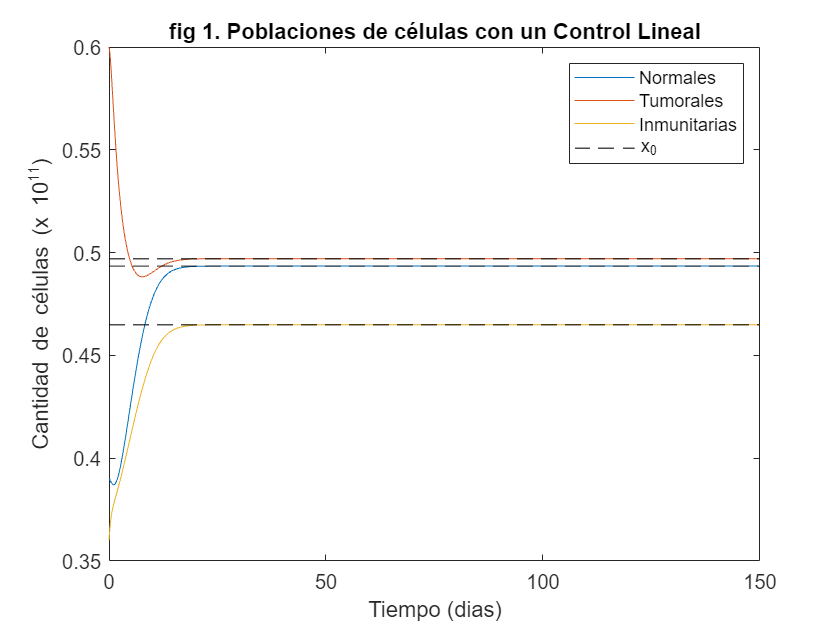

%peq=[0.4934 0.4970 0.4649 0.10]';
ci=[0.390 0.60 0.360 0.15]';
t=0:0.1:150;
ruido=[t' zeros(size(t,2),1)];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim('ControlLineal')
plot(t,[N T I])
yline(peq(1:3),'k--','LineWidth',0.7)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias" "x_0"])
title("fig 1. Poblaciones de células con un Control Lineal")

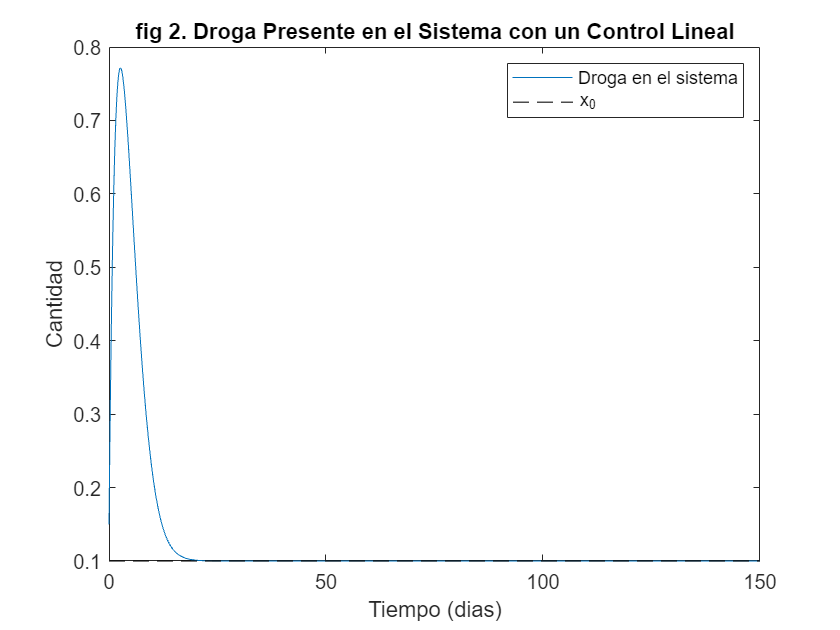

plot(t,u)
yline(peq(4),'k--','LineWidth',0.7)
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Droga en el sistema" "x_0"])
title("fig 2. Droga Presente en el Sistema con un Control Lineal")

En las figuras 1 y 2 podemos ver que al mover el sistema un poco del punto de operación, el control discreto hace regesar al sistema a dicho punto, lo que nos dice que funciona bien.

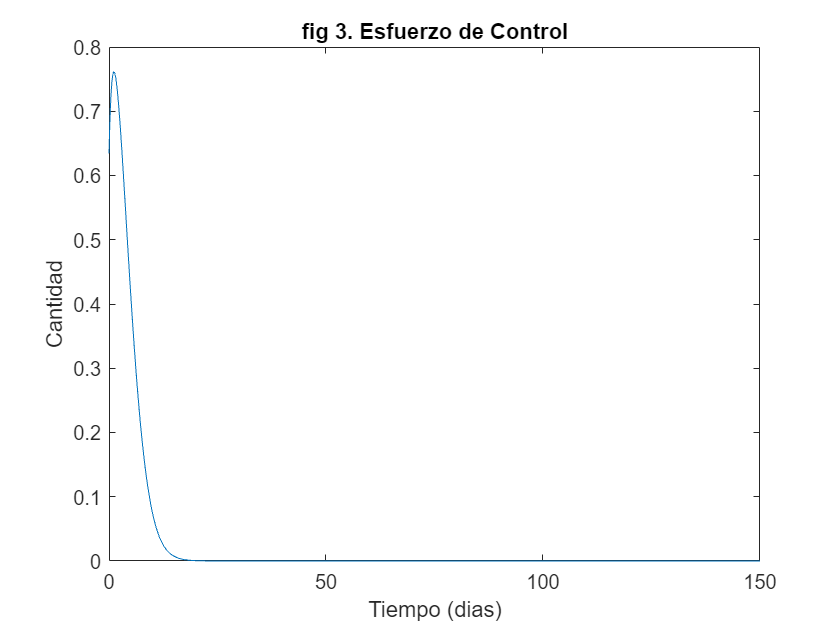

plot(t,Keff)
xlabel("Tiempo (dias)")
ylabel("Cantidad")
title("fig 3. Esfuerzo de Control")

La figura 3 nos muestra el esfuerzo hecho por el control continuo durante la simulación.

#### 3.1.3 Matriz de controlabilidad para el sistema discreto

Primero, encontraremos la matriz de controlabilidad para el sistema discreto, para evaluar la controlabilidad del sistema.

phi=sysDisc.A;
gamma=sysDisc.B;
Mc=[gamma phi*gamma phi^2*gamma phi^3*gamma];
r=rank(Mc);
nc=cond(Mc);
tab=array2table([r,nc],'VariableNames',{'Rango','Número de Condición'});
disp(tab)

    Rango    Número de Condición
    _____    ___________________

      4          1.4677e+07     



#### 3.1.4 Control lineal discreto

Haciendo el mismo procedimiento anterior, haremos un control lineal para el modelo pero discreto.

Pd=exp(P*Ts);
Kd=acker(phi,gamma,Pd);
disp(Kd)

    1.7402   -1.6021    0.5895    0.0911



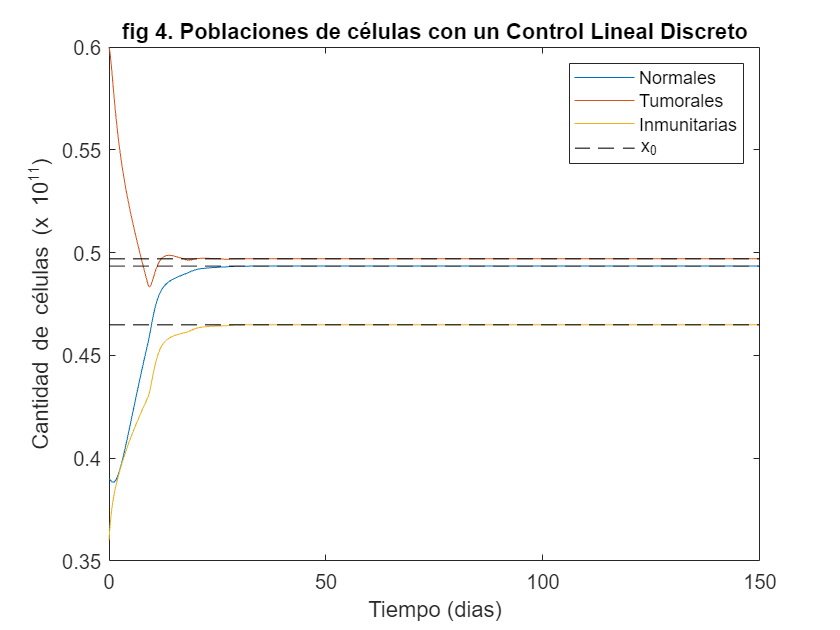

ci=[0.390 0.60 0.360 0.15]';
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim('ControlLinealDisc')
plot(t,[N T I])
yline(peq(1:3),'k--','LineWidth',0.7)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias" "x_0"])
title("fig 4. Poblaciones de células con un Control Lineal Discreto")

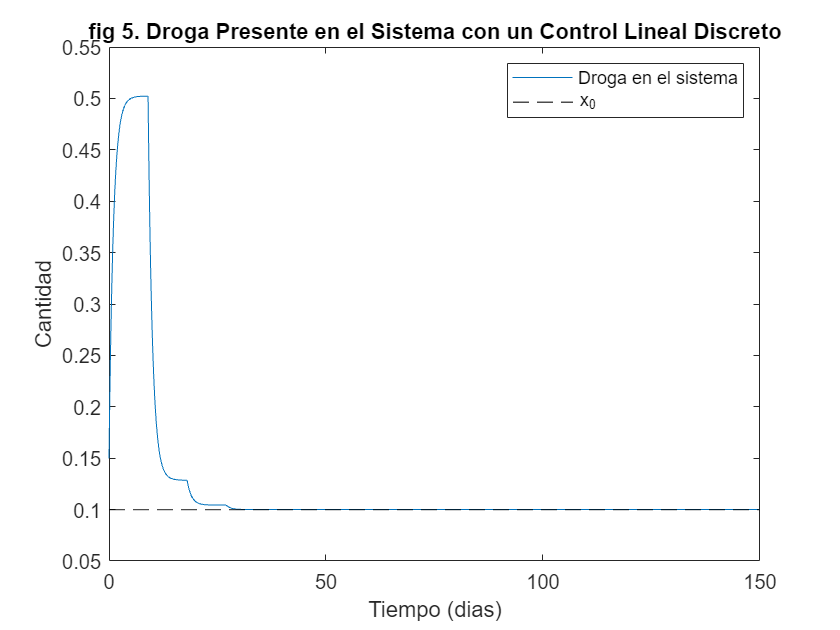

plot(t,u)
yline(peq(4),'k--','LineWidth',0.7)
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Droga en el sistema" "x_0"])
title("fig 5. Droga Presente en el Sistema con un Control Lineal Discreto")

En las figuras 4 y 5 podemos ver que al mover el sistema un poco del punto de operación, el control discreto hace regesar al sistema a dicho punto, lo que nos dice que funciona bien, como con el modelo continuo.

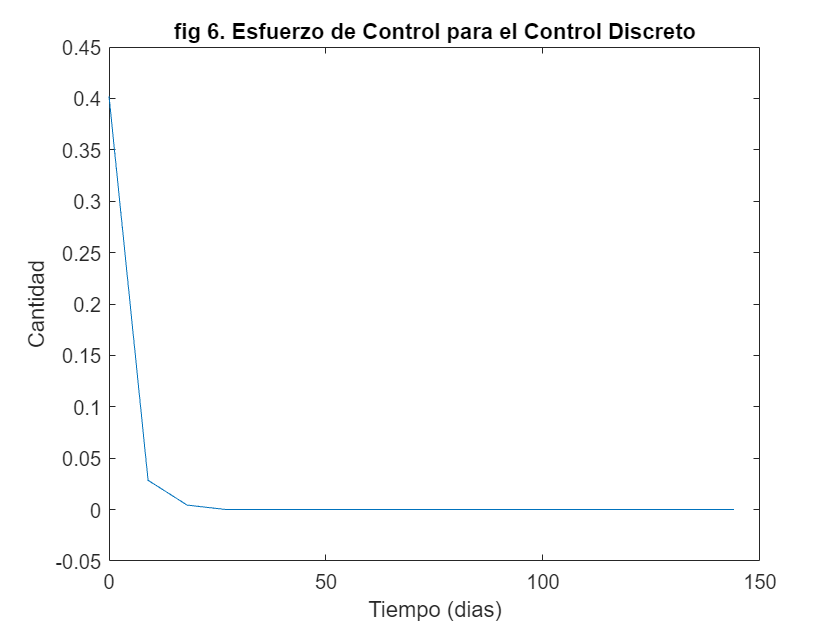

plot(0:Ts:150,Keff)
xlabel("Tiempo (dias)")
ylabel("Cantidad")
title("fig 6. Esfuerzo de Control para el Control Discreto")

La figura 6 nos muestra el esfuerzo hecho por el control discreto durante la simulación.

### 3.2. Simulaciones con el control lineal teniendo perturbaciones en la entrada

Ahora, haremos múltiples simulaciones usando el control lineal, en cada una se agregará una perturbación a la entrada del sistema en forma de pulsos de distintas alturas y anchos. Esto se hará para el control continuo y el discreto.

#### 3.2.1. Control de tiempo continuo

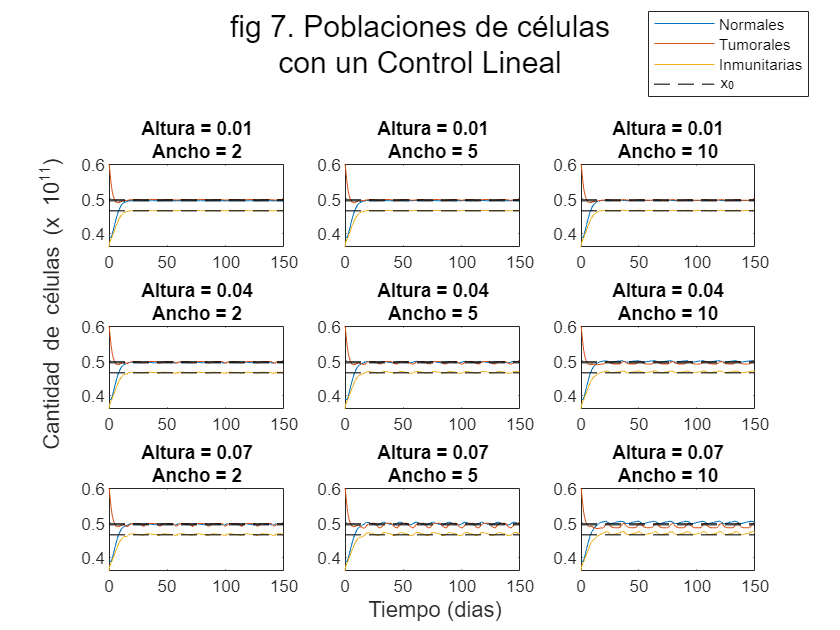

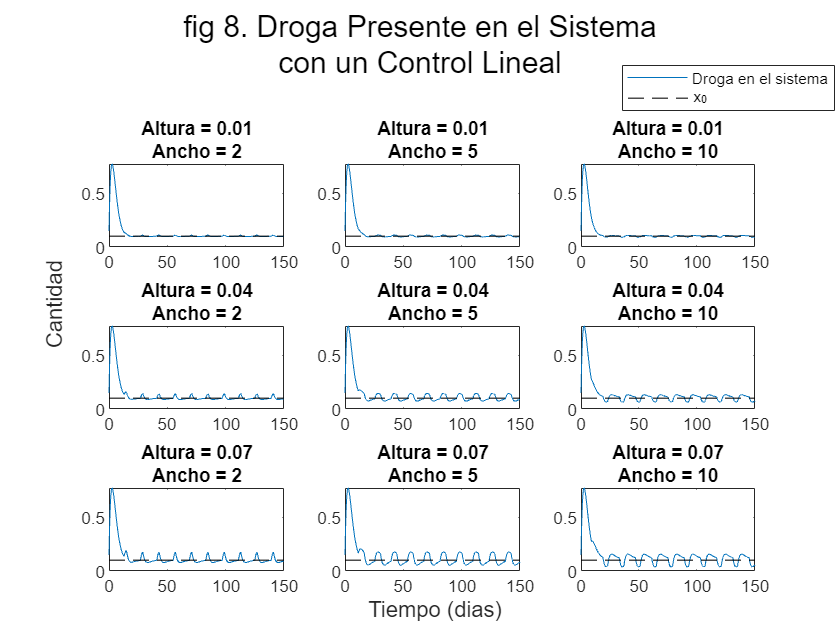

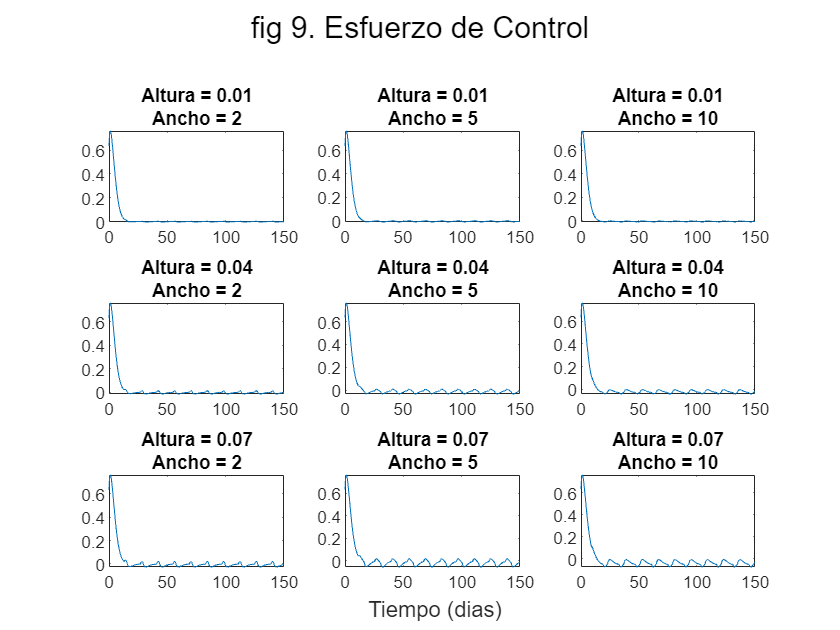

altura=0.01:0.03:0.07;
ancho=[2 5 10];
comb=table2array(combinations(altura,ancho));
periodo=14;
t=0:0.1:150;
val=0:periodo:150;
ruido=[t' zeros(size(t,2),1)];
for i=1:length(comb)
    h=comb(i,1);
    w=comb(i,2);
    d=[val;[0 h*ones(1,length(val)-1)]]';
    ruido(:,2)=pulstran(t,d,@rectpuls,w);
    sim('ControlLineal')
    figure(1)
    subplot(3,3,i)    
    plot(t,[N T I])
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
    yline(peq(1:3),'k--','LineWidth',0.7);
    figure(2)
    subplot(3,3,i)    
    plot(t,u)
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
    yline(peq(4),'k--','LineWidth',0.7);
    figure(3)
    subplot(3,3,i)
    plot(t,Keff)
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
end

figure(1)
sgtitle(["fig 7. Poblaciones de células", "con un Control Lineal"]);
figure(2)
sgtitle(["fig 8. Droga Presente en el Sistema", "con un Control Lineal"]);
figure(3)
sgtitle("fig 9. Esfuerzo de Control");

leg={["Normales" "Tumorales" "Inmunitarias" "x_0"];["Droga en el sistema" "x_0"]};
for i=1:3
    fig=figure(i);
    if i==3
        han=axes(fig,'visible','off'); 
        han.XLabel.Visible='on';
        xlabel("Tiempo (dias)")
        break
    end
    Lgnd = legend('show');
    Lgnd.Position(1) = 0.8;
    Lgnd.Position(2) = 0.83;
    legend(leg{i})
    han=axes(fig,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    xlabel("Tiempo (dias)")
    if i==2
        ylabel("Cantidad")
    else
        ylabel("Cantidad de células (x 10^{11})")
    end
end

Como podemos ver, las figuras 7 y 8 muestran los valores de cada estado al agregar perturbaciones en forma de pulso usando el control lineal continuo. La figura 9 nos presenta el esfuerzo de control para cada pulso, podemos ver que este disminuye con el tiempo ya que el sistema se acerca al punto de operación y aumenta debido a que los pulsos alejan al sistema de dicho punto.

#### 3.2.2. Control de tiempo discreto

Ahora se hará lo mismo con el control discreto.

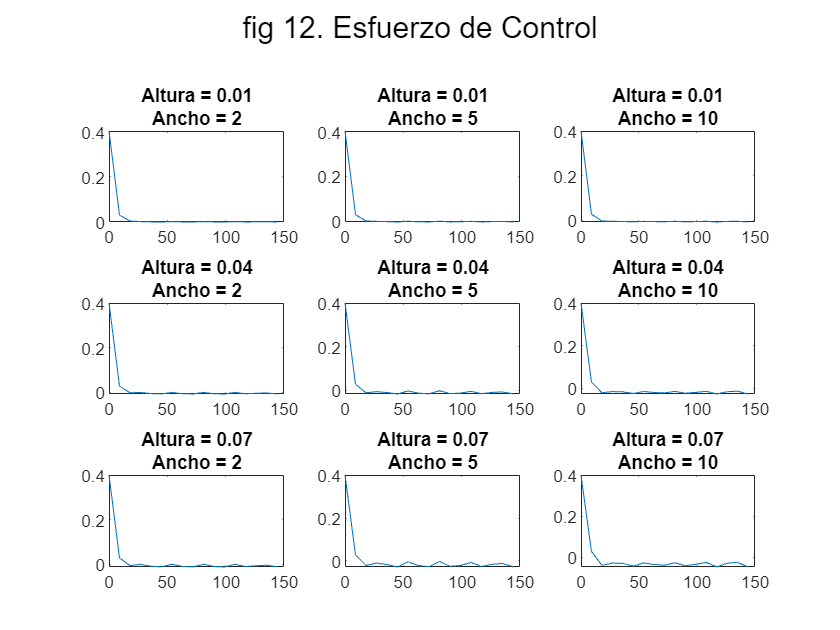

altura=0.01:0.03:0.07;
ancho=[2 5 10];
comb=table2array(combinations(altura,ancho));
periodo=14;
t=0:0.1:150;
val=0:periodo:150;
ruido=[t' zeros(size(t,2),1)];
for i=1:length(comb)
    h=comb(i,1);
    w=comb(i,2);
    d=[val;[0 h*ones(1,length(val)-1)]]';
    ruido(:,2)=pulstran(t,d,@rectpuls,w);
    sim('ControlLinealDisc')
    figure(4)
    subplot(3,3,i)    
    plot(t,[N T I])
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
    yline(peq(1:3),'k--','LineWidth',0.7);
    figure(5)
    subplot(3,3,i)    
    plot(t,u)
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
    yline(peq(4),'k--','LineWidth',0.7);
    figure(6)
    subplot(3,3,i)
    plot(0:Ts:150,Keff)
    title(["Altura = "+string(h),"Ancho = "+string(w)]);
end

figure(4)
sgtitle(["fig 10. Poblaciones de células", "con un Control Lineal Discreto"]);
figure(5)
sgtitle(["fig 11. Droga Presente en el Sistema", "con un Control Lineal Discreto"]);
figure(6)
sgtitle("fig 12. Esfuerzo de Control");

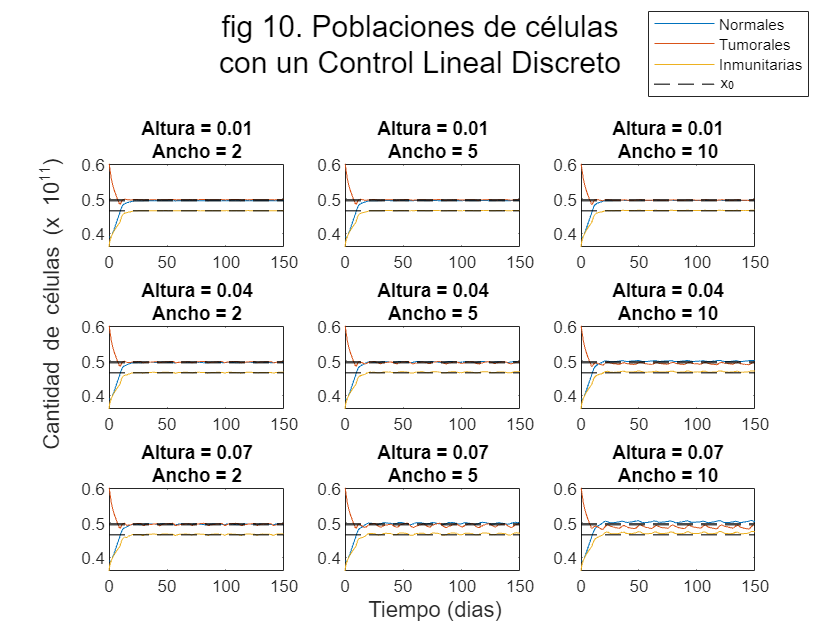

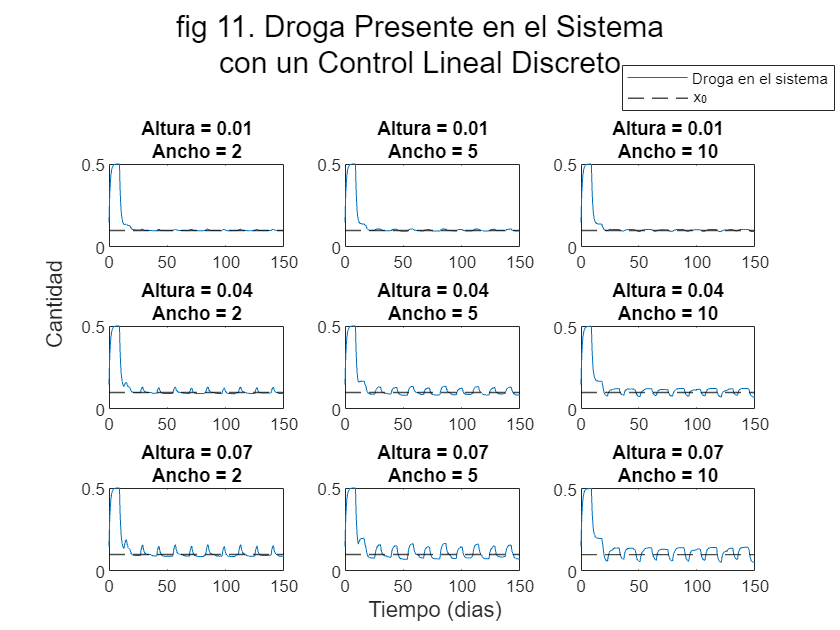

leg={["Normales" "Tumorales" "Inmunitarias" "x_0"];["Droga en el sistema" "x_0"]};
for i=1:2
    fig=figure(i+3);
    if i==3
        han=axes(fig,'visible','off'); 
        han.XLabel.Visible='on';
        xlabel("Tiempo (dias)")
        break
    end
    Lgnd = legend('show');
    Lgnd.Position(1) = 0.8;
    Lgnd.Position(2) = 0.83;
    legend(leg{i})
    han=axes(fig,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    xlabel("Tiempo (dias)")
    if i==2
        ylabel("Cantidad")
    else
        ylabel("Cantidad de células (x 10^{11})")
    end
end

Como podemos ver, las figuras 10 y 11 muestran los valores de cada estado al agregar perturbaciones en forma de pulso usando el control lineal continuo. La figura 12 nos presenta el esfuerzo de control para cada pulso, podemos ver que este disminuye con el tiempo ya que el sistema se acerca al punto de operación y aumenta debido a que los pulsos alejan al sistema de dicho punto. Podemos ver que el comportamiento de los estados  y el control son similares a los del caso continuo.

### 3.3. Análisis de incertidumbre

Para el análisis de incertidumbre usamos un ruido en forma de pulsos con amplitud de 0.04, periodo de 14 y un ancho de 4.

### 3.4. Análisis de sensibilidad escalar

Similar a con el análisis de incertidumbre, usamos un ruido en forma de pulsos con amplitud de 0.04, periodo de 14 y un ancho de 4.

## 4. Discusión

## 5. Referencias 

De Pillis, Lisette G, & Radunskaya, Ami. 2003. The dynamics of an optimally controlled tumor model: A case study. *Mathematical and computer modelling*, 37(11), 1221–1244.

Carlos M. Velez S. (2023). Global sensitivity and uncertainty analysis (GSUA) (https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua), MATLAB Central File Exchange. Recuperado Mayo 31, 2023.

Jonathan C. Lansey (2023). Beautiful and distinguishable line colors + colormap (https://www.mathworks.com/matlabcentral/fileexchange/42673-beautiful-and-distinguishable-line-colors-colormap), MATLAB Central File Exchange. Recuperado Mayo 30, 2023.